clear all
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
file_name = 'testing_lab3.bag';

file_path = fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING',file_name);

min5_imu = rosbag(file_path);

bSel_min5_imu = select(min5_imu,'Topic','/imu');

msgStructs = readMessages(bSel_min5_imu,'DataFormat','struct');
msgStructs{1};

Time = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs);
Time_n = cellfun(@(m) double(m.Header.Stamp.Nsec),msgStructs);
Time_n = Time_n./10e9;
Time = Time+Time_n;
Time = Time - Time(1);

q_w = cellfun(@(m) double(m.Imu.Orientation.W),msgStructs);
q_x = cellfun(@(m) double(m.Imu.Orientation.X),msgStructs);
q_y = cellfun(@(m) double(m.Imu.Orientation.Y),msgStructs);
q_z = cellfun(@(m) double(m.Imu.Orientation.Z),msgStructs);

phi = atan2(2*(q_w.*q_x+q_y.*q_z),1-2*(q_x.^2+q_y.^2)); %(y) (rad)
psi = -pi/2 +2*atan2(sqrt(1+2.*(q_w.*q_y-q_x.*q_z)),sqrt(1-2.*(q_w.*q_y-q_x.*q_z))); %(z) (rad)
theta = atan2(2*(q_w.*q_z+q_x.*q_y),1-2*(q_y.^2+q_z.^2)); %(x) (rad)

phi_deg = phi*(180/pi); %(degrees)
psi_deg = psi*(180/pi); %(degrees)
theta_deg = theta*(180/pi); %(degrees)

mag_x = cellfun(@(m) double(m.MagField.MagneticField_.X),msgStructs);  %unitless (magnitude)
mag_y = cellfun(@(m) double(m.MagField.MagneticField_.Y),msgStructs);  %unitless (magnitude)
mag_z = cellfun(@(m) double(m.MagField.MagneticField_.Z),msgStructs);  %unitless (magnitude)

accel_x = cellfun(@(m) double(m.Imu.LinearAcceleration.X),msgStructs); %m/s^2
accel_y = cellfun(@(m) double(m.Imu.LinearAcceleration.Y),msgStructs); %m/s^2
accel_z = cellfun(@(m) double(m.Imu.LinearAcceleration.Z),msgStructs); %m/s^2

gyro_x = cellfun(@(m) double(m.Imu.AngularVelocity.X),msgStructs); %rad/s
gyro_x_deg  = gyro_x.*(180/pi);                 %degree/s
gyro_y = cellfun(@(m) double(m.Imu.AngularVelocity.Y),msgStructs); %rad/s
gyro_y_deg  = gyro_y.*(180/pi);                 %degree/s
gyro_z = cellfun(@(m) double(m.Imu.AngularVelocity.Z),msgStructs); %rad/s     %rad/s
gyro_z_deg  = gyro_z.*(180/pi);                 %degree/s

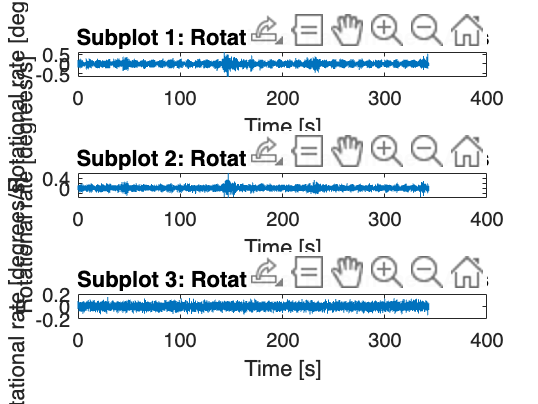

figure(1)
subplot(3,1,1);
plot(Time,gyro_x_deg)
title('Subplot 1: Rotational Rate in the X Axis')
xlabel('Time [s]')
ylabel('Rotational rate [degrees/s]')

subplot(3,1,2);
plot(Time,gyro_y_deg)
title('Subplot 2: Rotational Rate in the Y Axis')
xlabel('Time [s]')
ylabel('Rotational rate [degrees/s]')

subplot(3,1,3);
plot(Time,gyro_z_deg)
title('Subplot 3: Rotational Rate in the Z Axis')
xlabel('Time [s]')
ylabel('Rotational rate [degrees/s]')

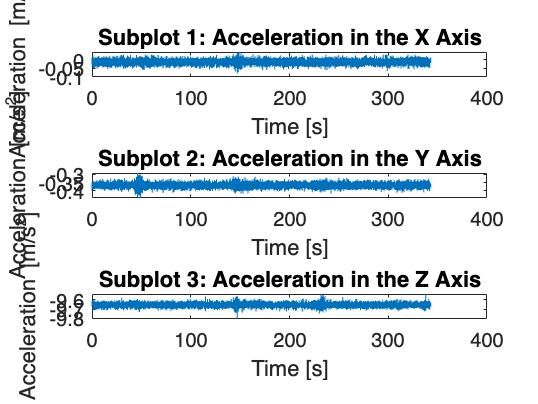

figure(2)
subplot(3,1,1);
plot(Time,accel_x)
title('Subplot 1: Acceleration in the X Axis')
xlabel('Time [s]')
ylabel('Acceleration [m/s^2]')

subplot(3,1,2);
plot(Time,accel_y)
title('Subplot 2: Acceleration in the Y Axis')
xlabel('Time [s]')
ylabel('Acceleration [m/s^2]')

subplot(3,1,3);
plot(Time,accel_z)
title('Subplot 3: Acceleration in the Z Axis')
xlabel('Time [s]')
ylabel('Acceleration [m/s^2]')

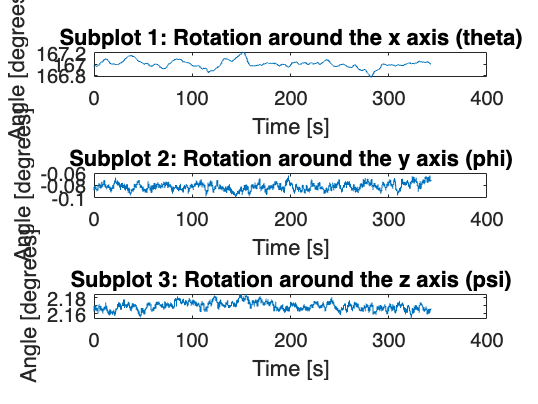

figure(3)
subplot(3,1,3);
plot(Time,psi_deg)
title('Subplot 3: Rotation around the z axis (psi)')
xlabel('Time [s]')
ylabel('Angle [degrees]')

subplot(3,1,2);
plot(Time,phi_deg)
title('Subplot 2: Rotation around the y axis (phi)')
xlabel('Time [s]')
ylabel('Angle [degrees]')

subplot(3,1,1);
plot(Time,theta_deg)
title('Subplot 1: Rotation around the x axis (theta)')
xlabel('Time [s]')
ylabel('Angle [degrees]')

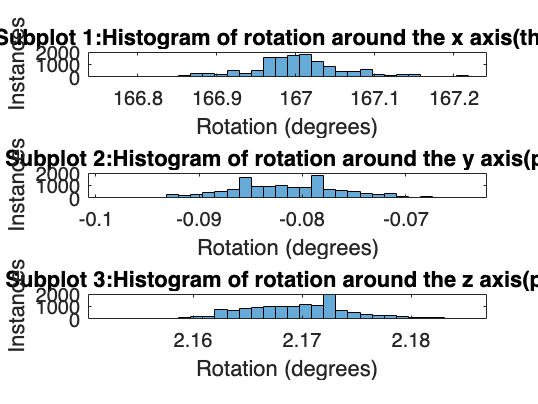

figure(4)
subplot(3,1,1);
histogram(theta_deg,30)
title('Subplot 1:Histogram of rotation around the x axis(theta)')
xlabel('Rotation (degrees)')
ylabel('Instances')

subplot(3,1,2);
histogram(phi_deg,30)
title('Subplot 2:Histogram of rotation around the y axis(phi)')
xlabel('Rotation (degrees)')
ylabel('Instances')

subplot(3,1,3);
histogram(psi_deg,30)
title('Subplot 3:Histogram of rotation around the z axis(psi)')
xlabel('Rotation (degrees)')
ylabel('Instances')